% theta1 from 0 - 0 to 180 - 2048
% theta2 from 135 - 1536 to 270 - 3072
% theta3 from 90 - 1024 to 315 - 3584
% q4 from 60 - 110 - 1254 to 98.8 - 180 - 2048

% baseH = 65.7
% L2 = 136.5
% L3 = 97.6
% EndH = variable (at 110, 60) (at 180, 98.8)

L1 = 65.7

L1 = 65.7000

L2 = 136.5

L2 = 136.5000

L3 = 97.6

L3 = 97.6000

syms theta1 theta2 theta3 q4
off1 = 90; off2 = 90; off3 = 90;
A1 = [cosd(theta1-off1) -sind(theta1-off1)*cosd(90) sind(theta1-off1)*sind(90) 0*cosd(theta1-off1); sind(theta1-off1) cosd(theta1-off1)*cosd(90) -cosd(theta1-off1)*sind(90) 0*sind(theta1-off1); 0 sind(90) cosd(90) L1; 0 0 0 1]

$$A1 = \left(\begin{array}{cccc} \cos\left(\frac{\pi \,\left(\theta_{1}-90\right)}{180}\right) & 0 & \sin\left(\frac{\pi \,\left(\theta_{1}-90\right)}{180}\right) & 0\\ \sin\left(\frac{\pi \,\left(\theta_{1}-90\right)}{180}\right) & 0 & -\cos\left(\frac{\pi \,\left(\theta_{1}-90\right)}{180}\right) & 0\\ 0 & 1 & 0 & \frac{657}{10}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A2 = [cosd(theta2-off2) -sind(theta2-off2)*cosd(0) sind(theta2-off2)*sind(0) L2*cosd(theta2-off2); sind(theta2-off2) cosd(theta2-off2)*cosd(0) -cosd(theta2-off2)*sind(0) L2*sind(theta2-off2); 0 sind(0) cosd(0) 0; 0 0 0 1]

$$A2 = \left(\begin{array}{cccc} \cos\left(\frac{\pi \,\left(\theta_{2}-90\right)}{180}\right) & -\sin\left(\frac{\pi \,\left(\theta_{2}-90\right)}{180}\right) & 0 & \frac{273\,\cos\left(\frac{\pi \,\left(\theta_{2}-90\right)}{180}\right)}{2}\\ \sin\left(\frac{\pi \,\left(\theta_{2}-90\right)}{180}\right) & \cos\left(\frac{\pi \,\left(\theta_{2}-90\right)}{180}\right) & 0 & \frac{273\,\sin\left(\frac{\pi \,\left(\theta_{2}-90\right)}{180}\right)}{2}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A3 = [cosd(theta3-off3) -sind(theta3-off3)*cosd(90) sind(theta3-off3)*sind(90) 0*cosd(theta3-off3); sind(theta3-off3) cosd(theta3-off3)*cosd(90) -cosd(theta3-off3)*sind(90) 0*sind(theta3-off3); 0 sind(90) cosd(90) 0; 0 0 0 1]

$$A3 = \left(\begin{array}{cccc} \cos\left(\frac{\pi \,\left(\theta_{3}-90\right)}{180}\right) & 0 & \sin\left(\frac{\pi \,\left(\theta_{3}-90\right)}{180}\right) & 0\\ \sin\left(\frac{\pi \,\left(\theta_{3}-90\right)}{180}\right) & 0 & -\cos\left(\frac{\pi \,\left(\theta_{3}-90\right)}{180}\right) & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A4 = [cosd(0) -sind(0)*cosd(0) sind(0)*sind(0) 0*cosd(0); sind(0) cosd(0)*cosd(0) -cosd(0)*sind(0) 0*sind(0); 0 sind(0) cosd(0) L3+q4; 0 0 0 1]

$$A4 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & q_{4}+\frac{488}{5}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


T2 = A1*A2;
T3 = T2*A3;
T4 = simplify(A1*A2*A3*A4)

$$T4 = \begin{array}{l} \left(\begin{array}{cccc} -\cos\left(\sigma_{4}\right)\,\sigma_{1} & \sin\left(\sigma_{3}\right) & -\sin\left(\sigma_{4}\right)\,\sigma_{1} & \frac{273\,\sigma_{1}\,\sigma_{5}}{2}-\sin\left(\sigma_{4}\right)\,\sigma_{1}\,\left(q_{4}+\frac{488}{5}\right)\\ \cos\left(\sigma_{4}\right)\,\sigma_{2} & -\cos\left(\sigma_{3}\right) & \sin\left(\sigma_{4}\right)\,\sigma_{2} & \sin\left(\sigma_{4}\right)\,\sigma_{2}\,\left(q_{4}+\frac{488}{5}\right)-\frac{273\,\sigma_{2}\,\sigma_{5}}{2}\\ -\sin\left(\sigma_{4}\right) & 0 & \cos\left(\sigma_{4}\right) & \frac{488\,\cos\left(\sigma_{4}\right)}{5}-\frac{273\,\cos\left(\frac{\pi \,\theta_{2}}{180}\right)}{2}+q_{4}\,\cos\left(\sigma_{4}\right)+\frac{657}{10}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\frac{\pi \,\theta_{1}}{180}\right)\\ \sigma_{2}=\cos\left(\frac{\pi \,\theta_{1}}{180}\right)\\ \sigma_{3}=\frac{\pi \,\left(\theta_{1}-90\right)}{180}\\ \sigma_{4}=\frac{\pi \,\left(\theta_{2}+\theta_{3}\right)}{180}\\ \sigma_{5}=\sin\left(\frac{\pi \,\theta_{2}}{180}\right) \end{array}$$

% the tip is at 0, 0, 0 in the 4th frame
tip = T4(1:3,4)

$$tip = \begin{array}{l} \left(\begin{array}{c} \frac{273\,\sigma_{3}\,\sigma_{2}}{2}-\sin\left(\sigma_{1}\right)\,\sigma_{3}\,\left(q_{4}+\frac{488}{5}\right)\\ \sin\left(\sigma_{1}\right)\,\sigma_{4}\,\left(q_{4}+\frac{488}{5}\right)-\frac{273\,\sigma_{4}\,\sigma_{2}}{2}\\ \frac{488\,\cos\left(\sigma_{1}\right)}{5}-\frac{273\,\cos\left(\frac{\pi \,\theta_{2}}{180}\right)}{2}+q_{4}\,\cos\left(\sigma_{1}\right)+\frac{657}{10} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\pi \,\left(\theta_{2}+\theta_{3}\right)}{180}\\ \sigma_{2}=\sin\left(\frac{\pi \,\theta_{2}}{180}\right)\\ \sigma_{3}=\sin\left(\frac{\pi \,\theta_{1}}{180}\right)\\ \sigma_{4}=\cos\left(\frac{\pi \,\theta_{1}}{180}\right) \end{array}$$

% create dataset using this
tip_fn = matlabFunction(tip, 'Vars', [theta1 theta2 theta3 q4]);
N = 50000;
t1 = 0   + 180*rand(N,1);
t2 = 135 + 135*rand(N,1);
t3 = 90  + 225*rand(N,1);
q  = 60  + 38.8*rand(N,1);

P = zeros(N,3);
for k = 1:N
    P(k,:) = tip_fn(t1(k), t2(k), t3(k), q(k))';
end

T = table(t1, t2, t3, q, P(:,1), P(:,2), P(:,3), 'VariableNames', {'theta1_deg','theta2_deg','theta3_deg','q4_mm','x_mm','y_mm','z_mm'});
writetable(T, 'arm_workspace_points.csv');

% plot
pose = [30 145 160 180];   % theta1 theta2 theta3 q4  (home = 90 180 180 110)
pts = [0 0 0; A1(1:3,4).'; T2(1:3,4).'; T3(1:3,4).'; tip.'];
pts_fn = matlabFunction(pts, 'Vars', [theta1 theta2 theta3 q4]);
Q = pts_fn(pose(1), pose(2), pose(3), pose(4))

Q =          0         0         0
         0         0   65.7000
   39.1466  -67.8039  177.5143
   39.1466  -67.8039  177.5143
  152.8449 -264.7351  336.7391


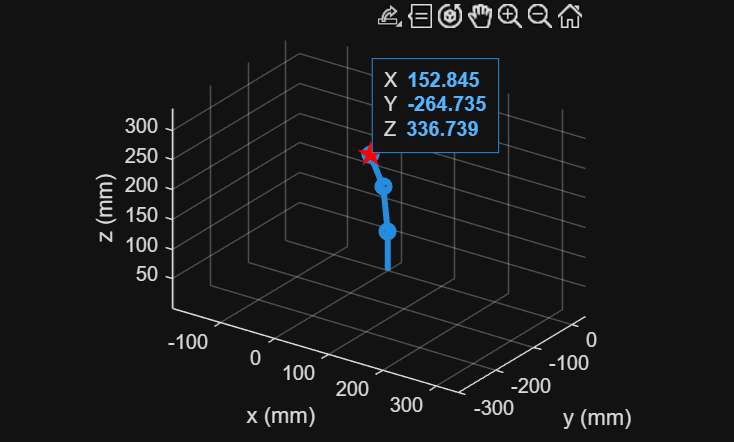


figure; hold on; grid on; axis equal
plot3(Q(:,1), Q(:,2), Q(:,3), '-o', 'LineWidth', 3)
plot3(Q(end,1), Q(end,2), Q(end,3), 'rp', 'MarkerFaceColor', 'r', 'MarkerSize', 12)
xlabel('x (mm)'); ylabel('y (mm)'); zlabel('z (mm)'); view(35, 25)